clc 
clear all
load('data_gauss');
rng(0);%same seed
MaxIt = 80;% Maximum number of iterations
normA=norm(A);% Norm of A
Af=1/norm(A,'fro')^2; % Frobenius norm of A
delta=0; db=zeros(M,1);%
db=db/norm(db);
delta=0.4*norm(b);
db=-0.5+rand(M,1); db=db/norm(db);
tol=10^-6;%Tolerance
b_delta=b+delta*db;%Noisy data
x_exact=x_gen;%Solution


xk=zeros(N,1); x_old=xk;%Initialization of Vanilla Primal-Dual
uk=zeros(M,1);

lambda=0.999/normA;%step sizes
[BD_Primal,Feas_Primal,Dist_Primal,Val_Primal,ES_Primal,EEI_Primal,Time_Tol_Primal,Iter_Tol_Primal,Time_Primal,Error_Primal] = ...
    PD_primal(xk,x_old,uk,lambda,MaxIt,A,b_delta,b,x_exact,mu_exact,normA,tol);%Vanilla Primal-Dual

% xk=zeros(N,1); %Initialization of Vanilla Dual - Primal
% uk=zeros(M,1); u_old=uk;
% 
% lambda=0.999/normA; %Step sizes
% 
% [BD_Dual,Feas_Dual,Dist_Dual, Val_Dual,ES_Dual,EEI_Dual,Time_Tol_Dual,Iter_Tol_Dual,Time_Dual,Error_Dual] = ...
%     PD_dual(xk,uk,u_old,lambda,MaxIt,A,b_delta,b,x_exact,mu_exact,normA,tol);%Vanilla Dual - Primal

xk=zeros(N,1);%Initialization of Douglas Rachford
 
lambda=1;%Step size
[BD_DR,Feas_DR,Dist_DR,Val_DR,ES_DR,EEI_DR,Time_Tol_DR,Iter_Tol_DR,Time_DR,Error_DR] = ...
     DouglRach_primal(xk,lambda,MaxIt,A,b_delta,b,x_exact,mu_exact,normA,tol);%Douglas Rachford

xk=zeros(N,1); pk=xk; p_old=xk;%Initialization of Primal-Dual with serial projections
uk=zeros(M,1);


lambda=0.999/normA;%Step sizes
  
prob_proj_primal=0.99;%Probability of projection

[BD_PROJ_primalseries,Feas_PROJ_primalseries,Dist_PROJ_primalseries,Val_PROJ_primalseries,ES_PROJ_primalseries,EEI_PROJ_primalseries,Time_Tol_PROJ_primalseries,Iter_Tol_PROJ_primalseries,Time_PROJ_primalseries,Error_PROJ_primalseries] = ...
    PROJ_primalseries(xk,pk,p_old,uk,lambda,prob_proj_primal,MaxIt,A,b_delta,b,x_exact,mu_exact,normA,tol);%Primal-Dual with serial projections

xk=zeros(N,1); pk=xk; p_old=xk;%Initialization of Primal-Dual with parallel projections
uk=zeros(M,1);

lambda=0.999/normA;%Step sizes
  
prob_proj_primal=0.99;%Probability of projection

[BD_PROJ_primalparallel,Feas_PROJ_primalparallel,Dist_PROJ_primalparallel,Val_PROJ_primalparallel,ES_primalparallel,EEI_primalparallel,Time_Tol_primalparallel,Iter_Tol_primalparallel,Time_primalparallel,Error_primalparallel] = ...
    PROJ_primalparallel(xk,pk,p_old,uk,lambda,MaxIt,A,b_delta,b,x_exact,mu_exact,normA,Af,tol);
%Primal-Dual with parallel projections

xk=zeros(N,1); %Initialization with projections on the dual
uk=zeros(M,1); pk=uk; p_old=uk; 

lambda=0.999/normA;%Step sizes
  
prob_proj_dual=0.99;%Probaility of projections

[BD_PROJ_dual,Feas_PROJ_dual,Dist_PROJ_dual,Val_PROJ_dual,ES_PROJ_dual,EEI_PROJ_dual,Time_Tol_PROJ_dual,Iter_Tol_PROJ_dual,Time_PROJ_dual,Error_PROJ_dual] = ...
        PROJ_dual(xk,uk,pk,p_old,lambda,prob_proj_dual,MaxIt,A,b_delta,b,x_exact,mu_exact,normA,tol);
%Initialization of Primal-Dual on the dual

xk=zeros(N,1); pk=xk; p_old=xk;%Initialization of Primal-Dual with fix landwenber step
uk=zeros(M,1);

lambda=0.999/normA;% Step size

[BD_PROJ_primalandaptative,Feas_PROJ_primalandaptative,Dist_PROJ_primalandaptative,Val_PROJ_primalandaptative,ES_PROJ_primalandaptative,EEI_PROJ_primalandaptative,Time_Tol_PROJ_primalandaptative,Iter_Tol_PROJ_primalandaptative,Time_PROJ_primalandaptative, Error_PROJ_primalandaptative] = ...
    PROJ_primalandaptative(xk,pk,p_old,uk,lambda,MaxIt,A,b_delta,b,x_exact,mu_exact,normA,tol,1);%Primal-Dual with fix landwenber step

 xk=zeros(N,1); pk=xk; p_old=xk;%Initialization of Primal-Dual with adaptive landwenber step
uk=zeros(M,1);

lambda=0.999/normA;%step size
  
[BD_PROJ_primalland,Feas_PROJ_primalland,Dist_PROJ_primalland,Val_PROJ_primalland,ES_PROJ_primalland,EEI_PROJ_primalland,Time_Tol_PROJ_primalland,Iter_Tol_PROJ_primalland,Time_PROJ_primalland,Error_PROJ_primalland] = ...
    PROJ_primalland(xk,pk,p_old,uk,lambda,MaxIt,A,b_delta,b,x_exact,mu_exact,normA,tol,2/normA^2);%Primal-Dual with adaptive landwenber step

% xk=zeros(N,1); x_old=xk;
% uk=zeros(M,1);
% lambda=0.999/normA;
% [BD_W,Feas_W,Dist_W,Val_W,ES_W,EST_W,ESI_W,Time_Tol_W,Iter_Tol_W,Time_W,Error_W] = PDW_primal(xk,x_old,uk,lambda,MaxIt,A,b_delta,b,x_exact,mu_exact,normA,tol);

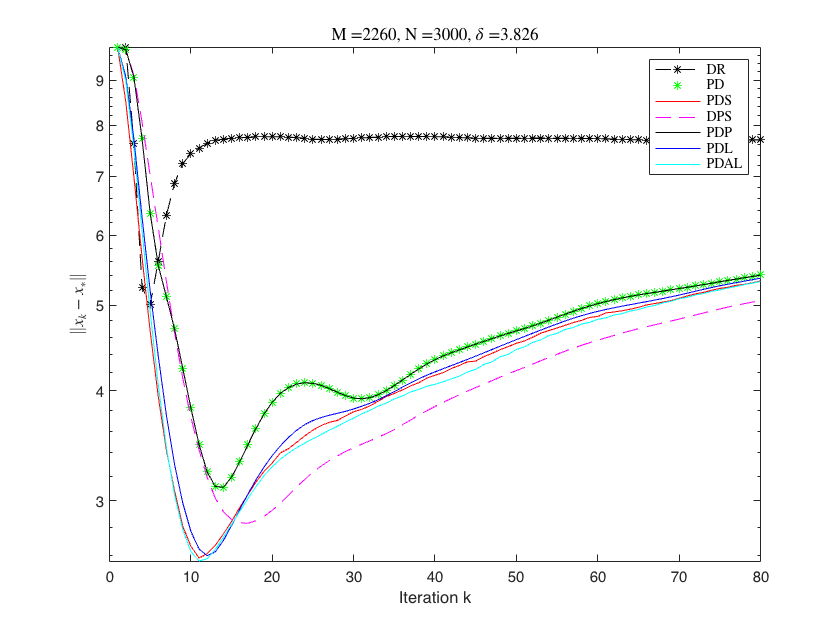

NN=1:MaxIt;%Plot of Norm error, feasibility value, function value, and Lagrangian Gap respectively. 
% figure; semilogy(NN, Dist_Primal, 'g',...
%     NN, Dist_PROJ_primalseries, 'k',... 
%     NN, Dist_PROJ_dual, 'r',...
%     NN, Dist_PROJ_primalparallel, 'm',...
%     NN, Dist_PROJ_primalandaptative, 'c',...
%     NN, Dist_PROJ_primalland, 'y')
% legend('PD',...
%     'PDS',...
%     'DPS',...
%     'PDP',...
%     'PDL',...
%     'PDAL','Interpreter','latex')
% title(strcat('M =  ', num2str(M),...
%     ', N =  ', num2str(N),...
%     ', $\delta$ =  ', num2str(delta)),...
%     'Interpreter','latex')
% xlabel('Iteration k') 
% ylabel('$\|x_k-x_*\|$','Interpreter','latex')
%  
% figure; semilogy(NN, Feas_Primal, 'g',...
%     NN, Feas_PROJ_primalseries, 'k',... 
%     NN, Feas_PROJ_dual, 'r',...
%     NN, Feas_PROJ_primalparallel, 'm',...
%     NN, Feas_PROJ_primalandaptative, 'c',...
%     NN, Feas_PROJ_primalland, 'y')
% legend('PD',...
%     'PDS',...
%     'DPS',...
%     'PDP',...
%     'PDL',...
%     'PDAL','Interpreter','latex')
% title(strcat('M =  ', num2str(M),...
%     ', N =  ', num2str(N),...
%     ', $\delta$ =  ', num2str(delta)),...
%     'Interpreter','latex')
% xlabel('Iteration k') 
% ylabel('$\|Ax_k-b^\delta\|$','Interpreter','latex')
% 
% legend('Position',[0.68401,1.0316,0.26103,0.22357])
% figure; semilogy(NN, Val_Primal, 'g',...
%     NN, Val_PROJ_primalseries, 'k',... 
%     NN, Val_PROJ_dual, 'r',...
%     NN, Val_PROJ_primalparallel, 'm',...
%     NN, Val_PROJ_primalandaptative, 'c',...
%     NN, Val_PROJ_primalland, 'y')
% legend('PD',...
%     'PDS',...
%     'DPS',...
%     'PDP',...
%     'PDL',...
%     'PDAL','Interpreter','latex')
% title(strcat('M =  ', num2str(M),...
%     ', N =  ', num2str(N),...
%     ', $\delta$ =  ', num2str(delta)),...
%     'Interpreter','latex')
% xlabel('Iteration k') 
% ylabel('$|J(x_*)-J(x^k)|$','Interpreter','latex')
% 
% figure; semilogy(NN, BD_Primal, 'g',...
%     NN, BD_PROJ_primalseries, 'k',... 
%     NN, BD_PROJ_dual, 'r',...
%     NN, BD_PROJ_primalparallel, 'm',...
%     NN, BD_PROJ_primalandaptative, 'c',...
%     NN, BD_PROJ_primalland, 'y')
% legend('PD',...
%     'PDS',...
%     'DPS',...
%     'PDP',...
%     'PDL',...
%     'PDAL','Interpreter','latex')
% title(strcat('M =  ', num2str(M),...
%     ', N =  ', num2str(N),...
%     ', $\delta$ =  ', num2str(delta)),...
%     'Interpreter','latex')
% xlabel('Iteration k') 
% ylabel('$\mathcal{L}(x^{k},u_*)-\mathcal{L}(x_*,u^{k})$','Interpreter','latex')
% save('re_NF_3000'); 

figure; semilogy(NN, Dist_DR,'k--*', ...
    NN, Dist_Primal, 'g*',...
    NN, Dist_PROJ_primalseries, 'r',... 
    NN, Dist_PROJ_dual, 'm--',...
    NN, Dist_PROJ_primalparallel, 'k',...
    NN, Dist_PROJ_primalland, 'b',...
    NN, Dist_PROJ_primalandaptative, 'c')
legend('DR',...
    'PD',...
    'PDS',...
    'DPS',...
    'PDP',...
    'PDL',...
    'PDAL','Interpreter','latex')
title(strcat('M =  ', num2str(M),...
    ', N =  ', num2str(N),...
    ', $\delta$ =  ', num2str(delta)),...
    'Interpreter','latex')
xlabel('Iteration k') 
ylabel('$\|x_k-x_*\|$','Interpreter','latex')

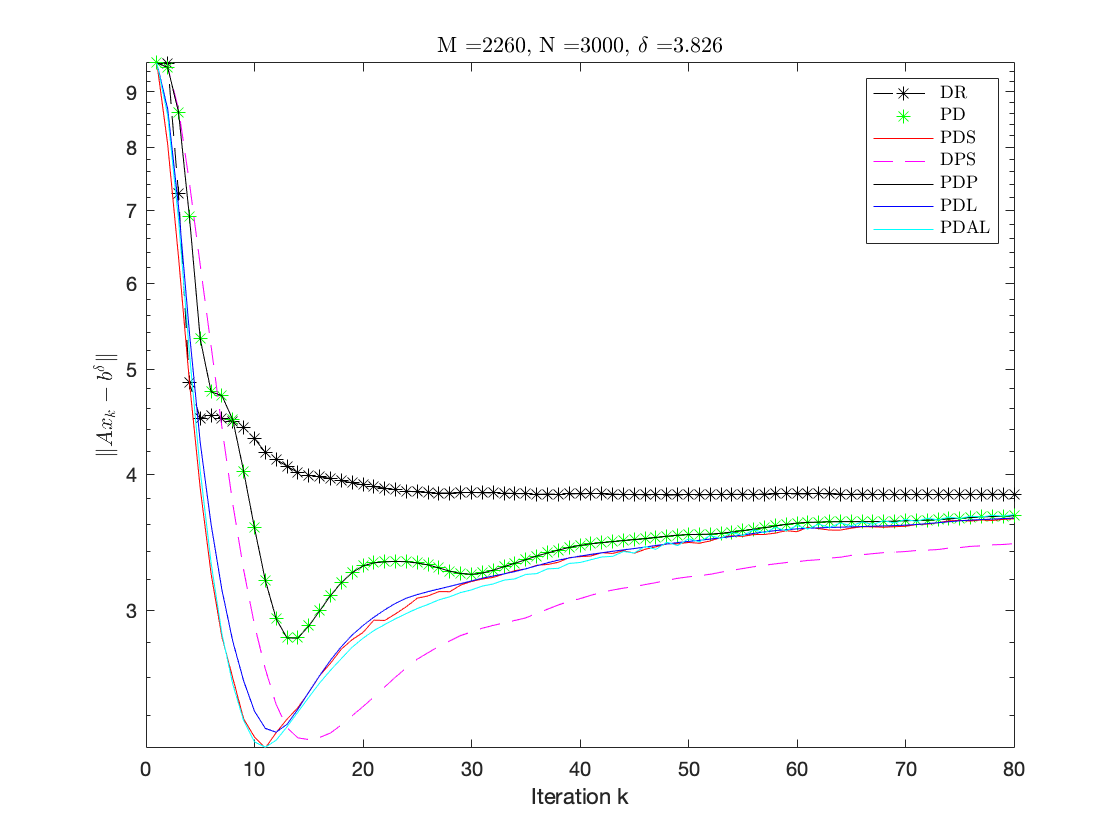

 
figure; semilogy(NN, Feas_DR,'k--*', ...
    NN, Feas_Primal, 'g*',...
    NN, Feas_PROJ_primalseries, 'r',... 
    NN, Feas_PROJ_dual, 'm--',...
    NN, Feas_PROJ_primalparallel, 'k',...
    NN, Feas_PROJ_primalland, 'b',...
    NN, Feas_PROJ_primalandaptative, 'c')
legend('DR',...
    'PD',...
    'PDS',...
    'DPS',...
    'PDP',...
    'PDL',...
    'PDAL','Interpreter','latex')
title(strcat('M =  ', num2str(M),...
    ', N =  ', num2str(N),...
    ', $\delta$ =  ', num2str(delta)),...
    'Interpreter','latex')
xlabel('Iteration k') 
ylabel('$\|Ax_k-b^\delta\|$','Interpreter','latex')

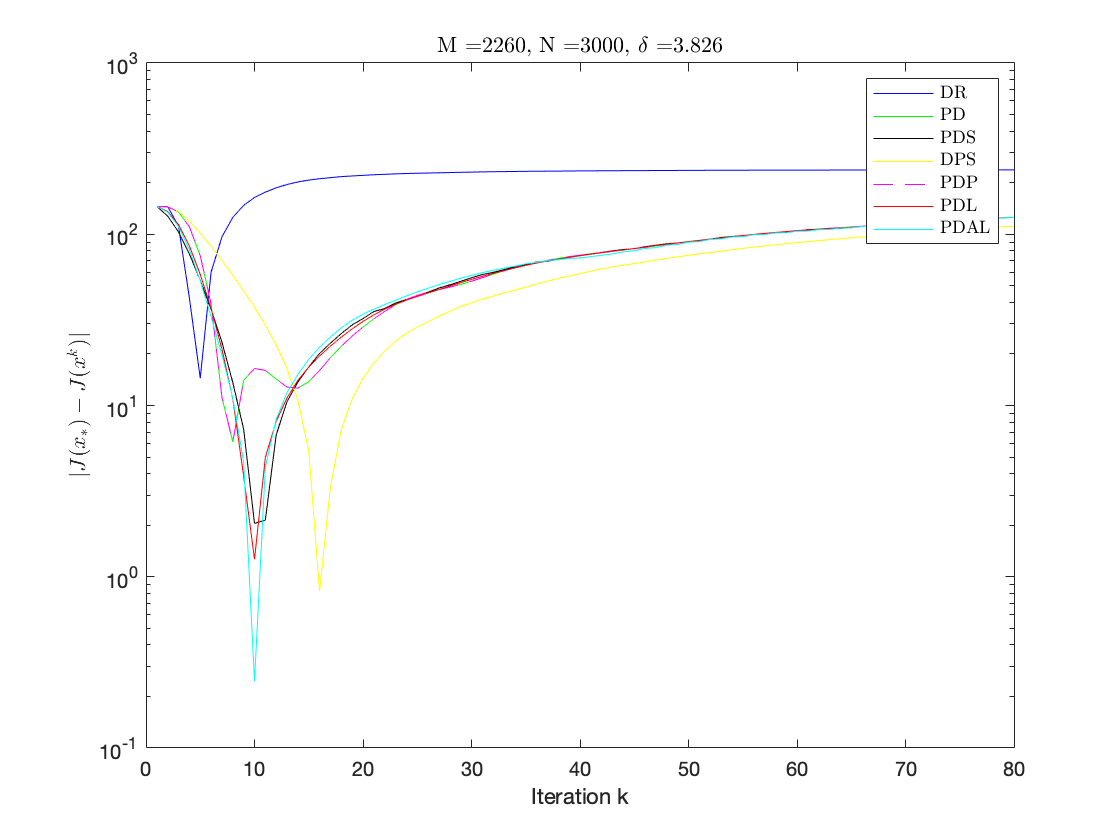

figure; semilogy(NN, Val_DR,'b', ...
    NN, Val_Primal, 'g',...
    NN, Val_PROJ_primalseries, 'k',... 
    NN, Val_PROJ_dual, 'y',...
    NN, Val_PROJ_primalparallel, 'm--',...
    NN, Val_PROJ_primalland, 'r',...
    NN, Val_PROJ_primalandaptative, 'c')
legend('DR',...
    'PD',...
    'PDS',...
    'DPS',...
    'PDP',...
    'PDL',...
    'PDAL','Interpreter','latex')
title(strcat('M =  ', num2str(M),...
    ', N =  ', num2str(N),...
    ', $\delta$ =  ', num2str(delta)),...
    'Interpreter','latex')
xlabel('Iteration k') 
ylabel('$|J(x_*)-J(x^k)|$','Interpreter','latex')

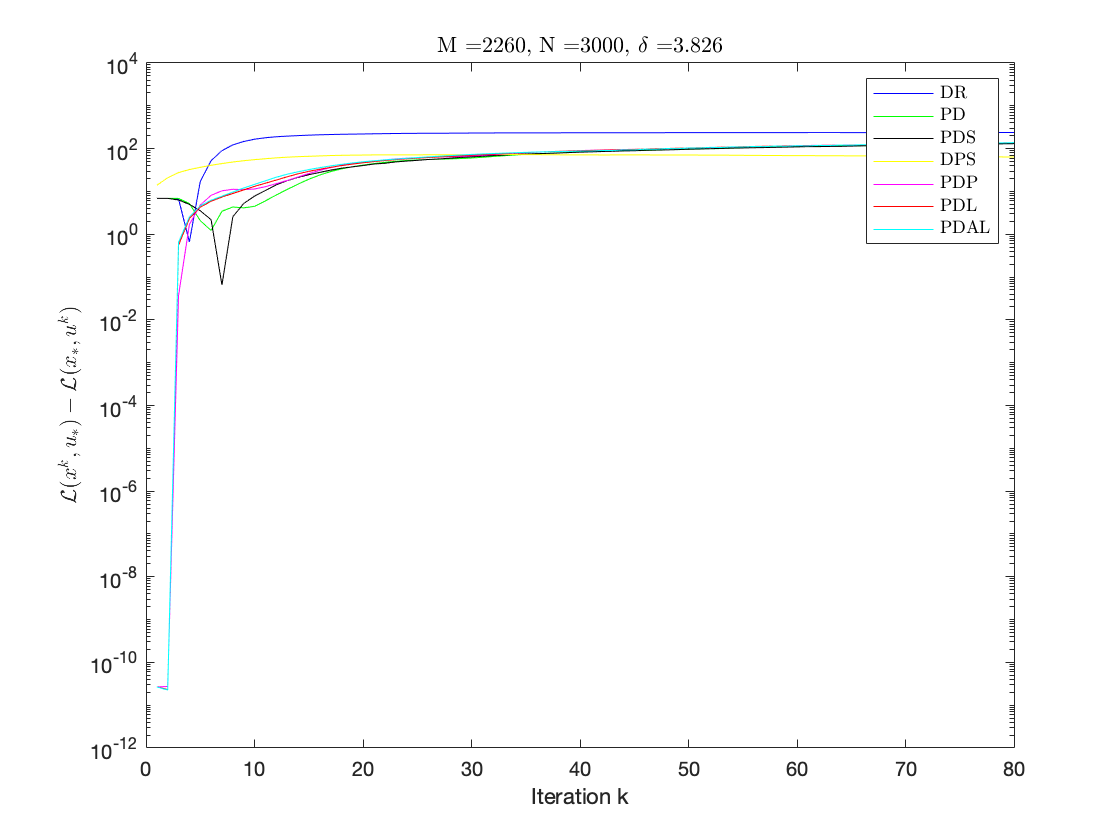


figure; semilogy(NN, BD_DR,'b', ...
    NN, BD_Primal, 'g',...
    NN, BD_PROJ_primalseries, 'k',... 
    NN, BD_PROJ_dual, 'y',...
    NN, BD_PROJ_primalparallel, 'm',...
    NN, BD_PROJ_primalland, 'r',...
    NN, BD_PROJ_primalandaptative, 'c')
legend('DR',...
    'PD',...
    'PDS',...
    'DPS',...
    'PDP',...
    'PDL',...
    'PDAL','Interpreter','latex')
title(strcat('M =  ', num2str(M),...
    ', N =  ', num2str(N),...
    ', $\delta$ =  ', num2str(delta)),...
    'Interpreter','latex')
xlabel('Iteration k') 
ylabel('$\mathcal{L}(x^{k},u_*)-\mathcal{L}(x_*,u^{k})$','Interpreter','latex')

save('re_NF_3000'); 

% LastName = {'PD';'PDS';'PDP';'DPS';'PDL';'PDAL'};
% Time_Tol = [Time_Tol_Primal;Time_Tol_PROJ_primalseries; Time_Tol_primalparallel; Time_Tol_PROJ_dual;Time_Tol_PROJ_primalandaptative;Time_Tol_PROJ_primalland];
% %Iteration_Tol = {Time_Tol_Primal;Time_Tol_DR;Time_Tol_PROJ_primalseries;Time_Tol_primalparallel;Time_Tol_PROJ_dual;Time_Tol_PROJ_primalandaptative;Time_Tol_PROJ_primalland}
% Iteration_Tol = [Iter_Tol_Primal;Iter_Tol_PROJ_primalseries; Iter_Tol_primalparallel; Iter_Tol_PROJ_dual;Iter_Tol_PROJ_primalandaptative;Iter_Tol_PROJ_primalland];
% Total_Time=[Time_Primal;Time_PROJ_primalseries;Time_primalparallel; Time_PROJ_dual;Time_PROJ_primalandaptative;Time_PROJ_primalland];
% 
% T1 = table(Iteration_Tol,Time_Tol,Total_Time,'RowNames',LastName)
% Early_Stopping = [ES_Primal;ES_PROJ_primalseries; ES_primalparallel; ES_PROJ_dual;ES_PROJ_primalandaptative;ES_PROJ_primalland];
% Early_Stopping_Time = [EEI_Primal;EEI_PROJ_primalseries; EEI_primalparallel; EEI_PROJ_dual;EEI_PROJ_primalandaptative;EEI_PROJ_primalland];
% ERROR=[Error_Primal;Error_PROJ_primalseries;Error_primalparallel; Error_PROJ_dual;Error_PROJ_primalandaptative;Error_PROJ_primalland];
% 
% T2 = table(Early_Stopping,Early_Stopping_Time,ERROR,'RowNames',LastName)
%Table with Number of iteration, time to reach the tolerance, time of execution
LastName = {'PD';'DR';'PDS';'PDP';'DPS';'PDAL';'PDL'};
Time_Tol = [Time_Tol_Primal;Time_Tol_DR;Time_Tol_PROJ_primalseries; Time_Tol_primalparallel; Time_Tol_PROJ_dual;Time_Tol_PROJ_primalandaptative;Time_Tol_PROJ_primalland];
%Iteration_Tol = {Time_Tol_Primal;Time_Tol_DR;Time_Tol_PROJ_primalseries;Time_Tol_primalparallel;Time_Tol_PROJ_dual;Time_Tol_PROJ_primalandaptative;Time_Tol_PROJ_primalland}
Iteration_Tol = [Iter_Tol_Primal;Iter_Tol_DR;Iter_Tol_PROJ_primalseries; Iter_Tol_primalparallel; Iter_Tol_PROJ_dual;Iter_Tol_PROJ_primalandaptative;Iter_Tol_PROJ_primalland];
Total_Time=[Time_Primal;Time_DR;Time_PROJ_primalseries;Time_primalparallel; Time_PROJ_dual;Time_PROJ_primalandaptative;Time_PROJ_primalland];

T1 = table(Iteration_Tol,Time_Tol,Total_Time,'RowNames',LastName)

T1 = 7×3 table
            Iteration_Tol    Time_Tol    Total_Time
            _____________    ________    __________

    PD           80           1.6941       1.6992  
    DR           80           1.3082        1.313  
    PDS          80           17.712       17.723  
    PDP          80           6.9247       6.9937  
    DPS          80           10.138       10.161  
    PDAL         80           4.4458       4.4851  
    PDL          80            3.477       3.5237  


LastName = {'PD';'DR';'PDS';'PDP';'DPS';'PDAL';'PDL'};
Early_Stopping = [ES_Primal;ES_DR;ES_PROJ_primalseries; ES_primalparallel; ES_PROJ_dual;ES_PROJ_primalandaptative;ES_PROJ_primalland];
Early_Stopping_Time = [EEI_Primal;EEI_DR;EEI_PROJ_primalseries; EEI_primalparallel; EEI_PROJ_dual;EEI_PROJ_primalandaptative;EEI_PROJ_primalland];
ERROR=[Error_Primal;Error_DR;Error_PROJ_primalseries;Error_primalparallel; Error_PROJ_dual;Error_PROJ_primalandaptative;Error_PROJ_primalland];

T2 = table(Early_Stopping,Early_Stopping_Time,ERROR,'RowNames',LastName)

T2 = 7×3 table
            Early_Stopping    Early_Stopping_Time    ERROR 
            ______________    ___________________    ______

    PD          0.30251               14             3.1095
    DR         0.061213                5             5.0106
    PDS          2.1086               11             2.5839
    PDP          1.3923               14             3.1087
    DPS          2.5274               17             2.8293
    PDAL         1.1095               11             2.5639
    PDL          0.5088               12             2.5997
